Written By Benjamin Arnold

clc; clear;

Set time scale to read the signals

t0=1000*55+1 %time start (5 second intervals)

t0 = 55001

tf=1000 * 44+1

tf = 44001

d =1

d = 1

This is where you read the file:

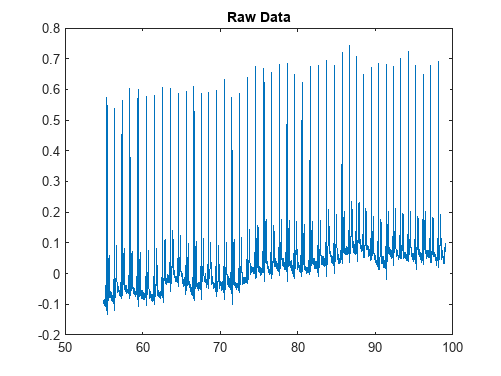

f = ECG_import("patient104_raw.csv",[t0,t0+tf]);

t= f.Time;
plot(t,f.i)
i=f.i;
ii=f.ii;
iii=f.iii;

title("Raw Data");

Find parameters

rind = ECG_FindR(f.i); 
ii = ECG_filtsig(f.ii,rind);
tind = ECG_FindR(ii,'T');
pind = ECG_FindR(ii,'P');
sind = ECG_FindR(f.v2,'S');

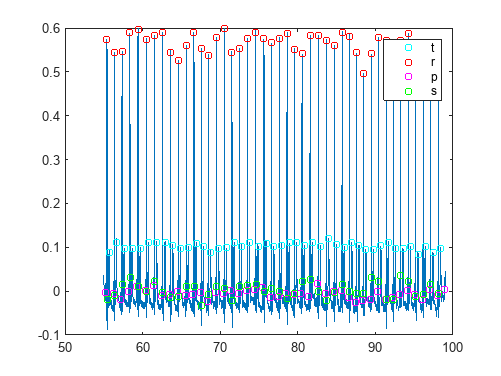

sigdisp= ECG_filtsig(f.i,rind);
plot(t,sigdisp)
hold on
plot(t(tind),sigdisp(tind),'co',MarkerSize=5)
plot(t(rind),sigdisp(rind),'ro',MarkerSize=5)
plot(t(pind),sigdisp(pind),'mo',MarkerSize=5)
plot(t(sind),sigdisp(sind),'go',MarkerSize=5)

legend('','t','r','p','s')
hold off

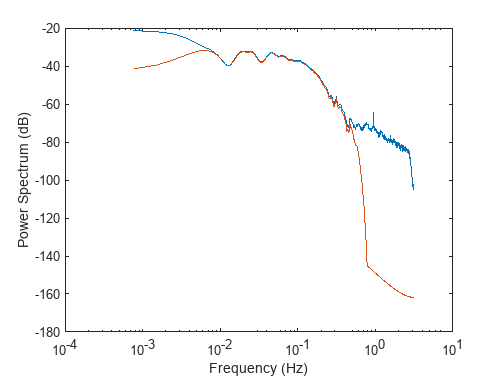

figure
[p,fr] = pspectrum(i);
semilogx(fr,db(p,"power"))
hold on
[p1,fr1] = pspectrum(sigdisp);
semilogx(fr1,db(p1,"power"))
hold off
xlabel("Frequency (Hz)")
ylabel("Power Spectrum (dB)")

Call heartbeat extract function

fi = table2array(f(:,16))';
ECG_hbeatextract(fi,1);

Call missing beat function

ECG_missingbeat(fi);

Call Gramian Angular function

ECG_GAF(fi,1)

Call 2D hear function

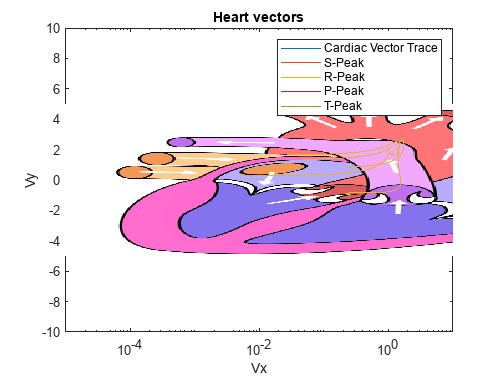

heartgraph(f);

Call 3D heart function

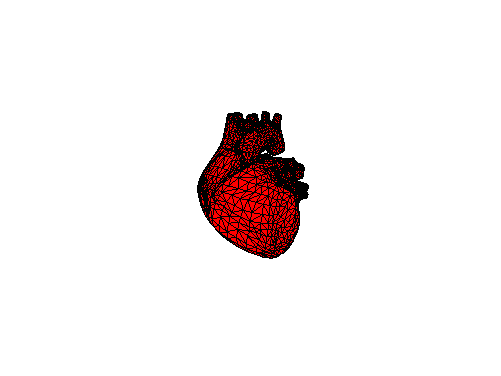

Dheart(f);